# Part 2- Image Processing

clear all

## **Finding the DFT of a window image**

Defining basic variables

N = 32;
M = 64;
B1 = 7;
B2 = B1;
j = sqrt(-1);

Finding y and it's DFT

y_num = zeros(N,1);
y_num(1:B1) = 1;
Y_num = fft(y_num);

Finding z and it's DFT

z_num = zeros(1,M);
z_num(1:B2) = 1;
Z_num = fft(z_num);

Combining Y and Z to a two dimensional signal

X_num = Y_num*Z_num;

Visualizing the results

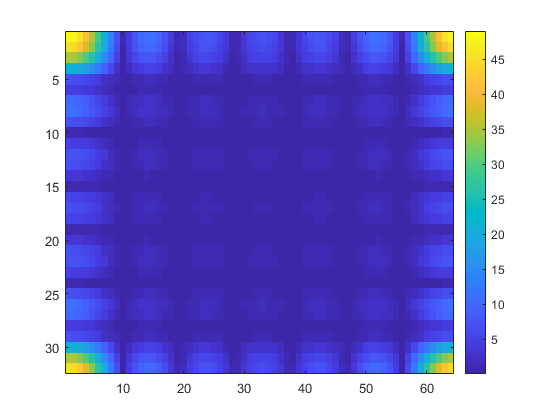

figure
imagesc(abs(X_num));
colorbar()

Comparing the nomeric results to the analytical results

n = 0:N-1;
m = 0:M-1;
Y_ana = D(2*pi*n/N,B1) .* exp(-j*pi*n*(B1-1)/N);
Z_ana = D(2*pi*m/M,B2) .* exp(-j*pi*m*(B2-1)/M);
X_ana  = Y_ana.' * Z_ana;
figure;
imagesc(abs(X_ana));
colorbar();

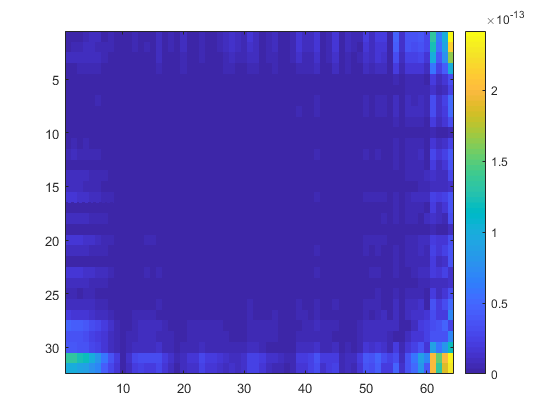

figure;
imagesc(abs(X_ana-X_num));
colorbar();

## **Introduction to the processing- playing with respond to **impulse 

Loading the given images

[dist_image_1,dist_image_2,noised_image,imp_resp_image] = img_gen('ITAY','IDO');

Visualizing all the images

dist_image_1

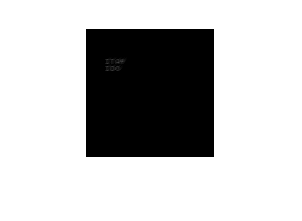

dist_image_2

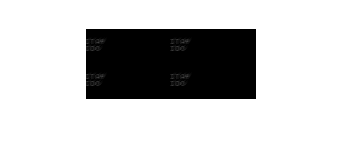

noised_image

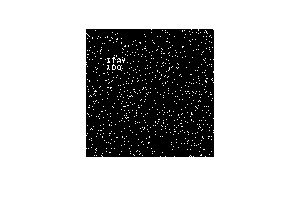

imp_resp_image

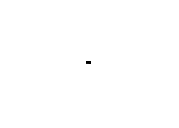

imgs = {dist_image_1,dist_image_2,noised_image,imp_resp_image};
names = {'dist_image_1','dist_image_2','noised_image','imp_resp_image'};
for i = 1:size(imgs,2)
    figure
    fprintf(names{i});
    imshow(imgs{i});
end

Extracting the 0'th column of h

h0 = imp_resp_image(:,1);
h0

h0 =          0
         0
    0.0909


Finding it's transform

N = size(h0,1)

N = 3

h0_pad = [h0; zeros(N,1)];
H0_pad = fft(h0_pad);

freq = [1,2,3,5];
sampled_freq = H0_pad(freq);
sampled_freq

sampled_freq =    0.0909 + 0.0000i
  -0.0455 - 0.0787i
  -0.0455 + 0.0787i
  -0.0455 - 0.0787i


Comparing to the theoretical values

(0.0909*exp(-j*2*pi*(freq-1)/3)).'

ans =    0.0909 + 0.0000i
  -0.0454 - 0.0787i
  -0.0455 + 0.0787i
  -0.0454 - 0.0787i


Creating a signal with two deltas  

L = 32;
w = zeros(L,1);
w([1,30]) = 1;
w'

ans =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0


Find the circular convolution of h0 and the deltas signal

h0_pad = [h0;zeros(L-N,1)];
H0_pad = fft(h0_pad);

W = fft(w);

Conv_res = H0_pad .* W;
conv_res = ifft(Conv_res);
conv_res' 

ans =     0.0000    0.0000    0.0909         0    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000         0    0.0000    0.0000         0    0.0909


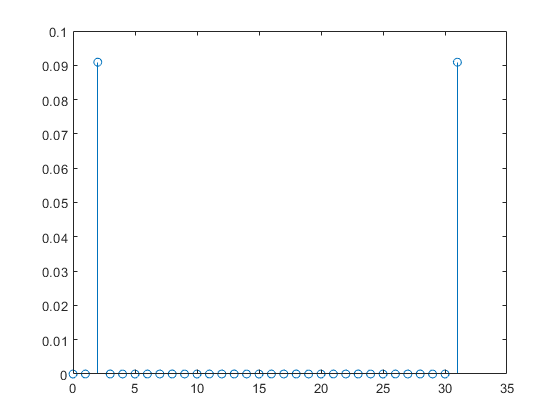

figure
stem(0:L-1,conv_res);

## **Restoring the noised image**

Restoring the first image

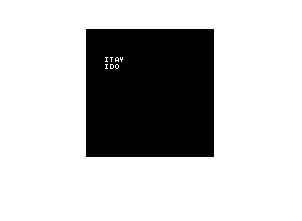

[N, M] = size(dist_image_1);
x1 = restore_image(dist_image_1,imp_resp_image);
figure
imshow(x1);

Restoring the second image 

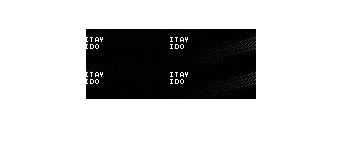

[N, M] = size(dist_image_2);
x2 = restore_image(dist_image_2,imp_resp_image);
figure
imshow(x2); 

Restoring the second image in a different way

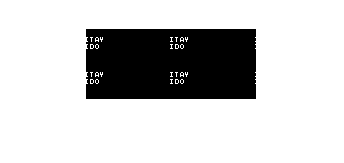

[N, M] = size(dist_image_2);
dist_image_2_cut = dist_image_2(1:N/2,1:M/2);
[N, M] = size(dist_image_2_cut);
x2_basic = restore_image(dist_image_2_cut,imp_resp_image);
x2_full = [x2_basic, x2_basic;x2_basic,x2_basic];
figure
imshow(x2_full);

Function to find Derichlet's kernel

function y = D(x,N)
    y = sin(0.5*x*N)./sin(0.5*x);
    y(isnan(y)) = N;
end

Function to find the 2 dimesional DFT of an image

% See PDF for proof of this method to find the DFT 
function X = fft_2D(x)
    X_col = fft(x); % Finds the DFT of each column 
    X = fft(X_col'); % Finds the DFT of the rows in the previous case 
end

Function to restore a noised image

function x = restore_image(y,h)    
    N = size(y);
    h_pad = padarray(h,N-size(h),'post');
    H_pad = fft_2D(h_pad);
    
    Y = fft_2D(y);
    X = Y ./ H_pad;
    x = fft_2D(1/(N(1)*N(2)) * conj(X));
    x = x(1:size(y,1),1:size(y,2));
end